disp('Loading data')

Loading data


% load('/Volumes/Samsung USB/MG49/MG49_Seizure36_interpolated.mat')

if ~exist('mea', 'var')
	mea = Neuroport;
	ecog = ECoG;
	clear Neuroport ECoG
end

set(groot, 'defaultLineLineWidth', 1);
set(groot, 'defaultAxesLineWidth', 1);
set(groot, 'defaultFigureColor', [1 1 1], 'defaultAxesFontSize', 16, 'defaultHistogramLineWidth',1);
% set(groot, 'defaultAxesFontWeight', 'bold');
set(groot, 'defaultAxesFontSize', 16);
c = lines(7);
aic = @(predictors, dev) dev + 2 * size(predictors, 2);

tmax = Inf;

## Filter

disp('Filtering');

Filtering


if ~isfield(mea, 'lfp')

	bpFilt = designfilt('bandpassfir','FilterOrder',150, ...
		'CutoffFrequency1',2,'CutoffFrequency2',50, ...
		'SampleRate', mea.SamplingRate);
	mea.lfp = single(filtfilt(bpFilt, double(mea.Data)));
	mea.lfp(:, mea.BadChannels) = [];

	bpFilt = designfilt('bandpassfir','FilterOrder',150, ...
		'CutoffFrequency1',2,'CutoffFrequency2',50, ...
		'SampleRate', ecog.SamplingRate);
	ecog.lfp = single(filtfilt(bpFilt, double(ecog.Data)));
	ecog.lfp(:, ecog.BadChannels) = [];

	bpFilt = designfilt('bandpassfir','FilterOrder',150, ...
		'CutoffFrequency1',3e2,'CutoffFrequency2',3e3, ...
		'SampleRate',mea.SamplingRate);
	mea.mua = single(filtfilt(bpFilt, double(mea.Data)));
	mea.mua(:, mea.BadChannels) = [];

	bpFilt = designfilt('bandpassfir', 'FilterOrder', 150, ...
		'CutoffFrequency1', 50, 'CutoffFrequency2', 300, ...
		'SampleRate', mea.SamplingRate);
	mea.highg = single(filtfilt(bpFilt, double(mea.Data)));
	mea.highg(:, mea.BadChannels) = [];

	bpFilt = designfilt('bandpassfir', 'FilterOrder', 150, ...
		'CutoffFrequency1', 50, 'CutoffFrequency2', 124, ...  % 150 in the Schevon paper, but max is 124.93 given sampling freq
		'SampleRate', ecog.SamplingRate);
	ecog.highg = single(filtfilt(bpFilt, double(ecog.Data)));
	ecog.highg(:, ecog.BadChannels) = [];

	mea.X = mea.ElectrodeXY(:, 1);
	mea.X(mea.BadChannels) = [];

	mea.Y = mea.ElectrodeXY(:, 2);
	mea.Y(mea.BadChannels) = [];

	ecog.X = ecog.ElectrodeXY(:, 1);
	ecog.X(ecog.BadChannels) = [];
	ecog.Y = ecog.ElectrodeXY(:, 2);
	ecog.Y(ecog.BadChannels) = [];
end

## Get MUA events

Negative peaks in this signal were detected and those peaks that exceeded four times the s.d. of the signal in the negative direction, and that occurred >1ms after immediately preceding peaks, were retained as multiunit timestamps and waveforms (Smith et al., 2016)

disp('Getting MUA events');

Getting MUA events



if ~isfield(mea, 'events')
	mea = mua_events(mea);
end

## Compute firing rate

Firing rate was calculated from these multiunit timestamps in 100-ms windows every 25 ms (Smith et al., 2016)

disp('Computing firing rate');

Computing firing rate



if ~isfield(mea, 'firingRate')
	mea = mua_firing_rate(mea);
end

## Test for recruitment

Use the methods outlined in Schevon et al., 2012 to see if the MEA territory was recruited into the seizure. This includes looking at the coherence and Fano factor.

disp('Computing coherence')

Computing coherence and Fano factor


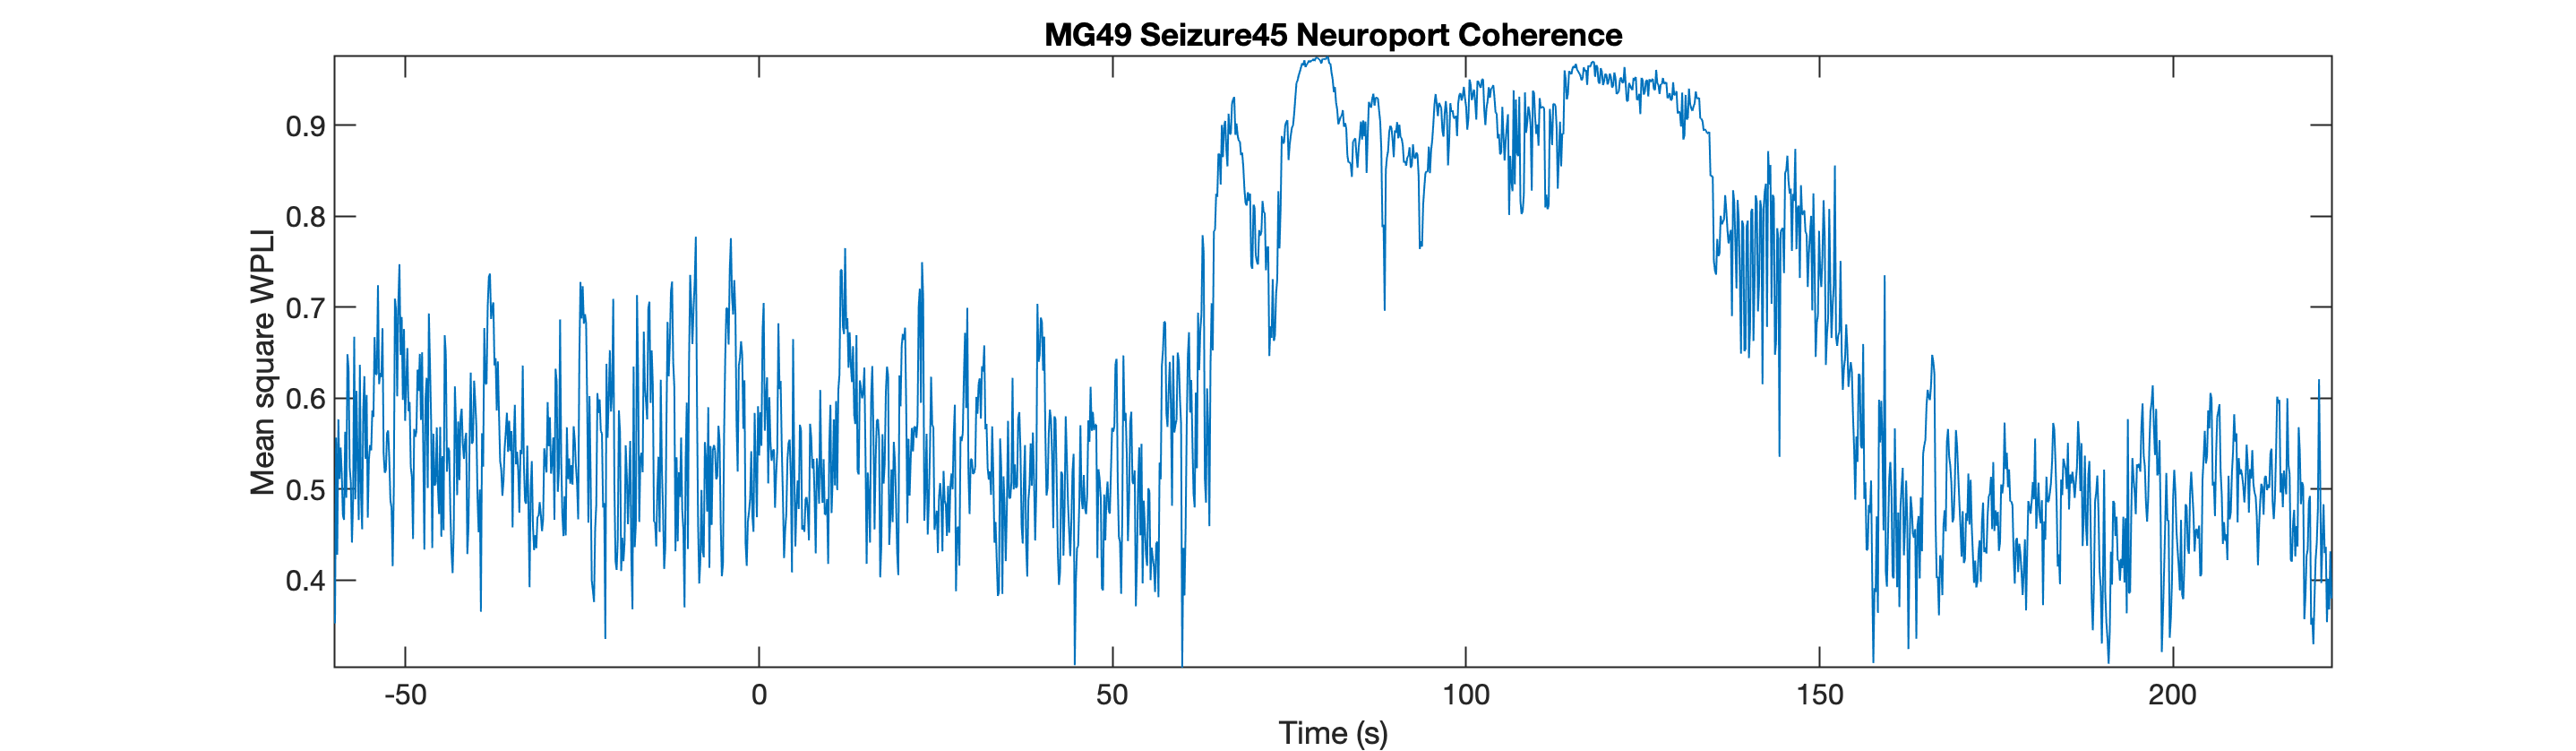


if ~isfield(mea, 'wpli')
	mea = test_for_recruitment(mea);
end

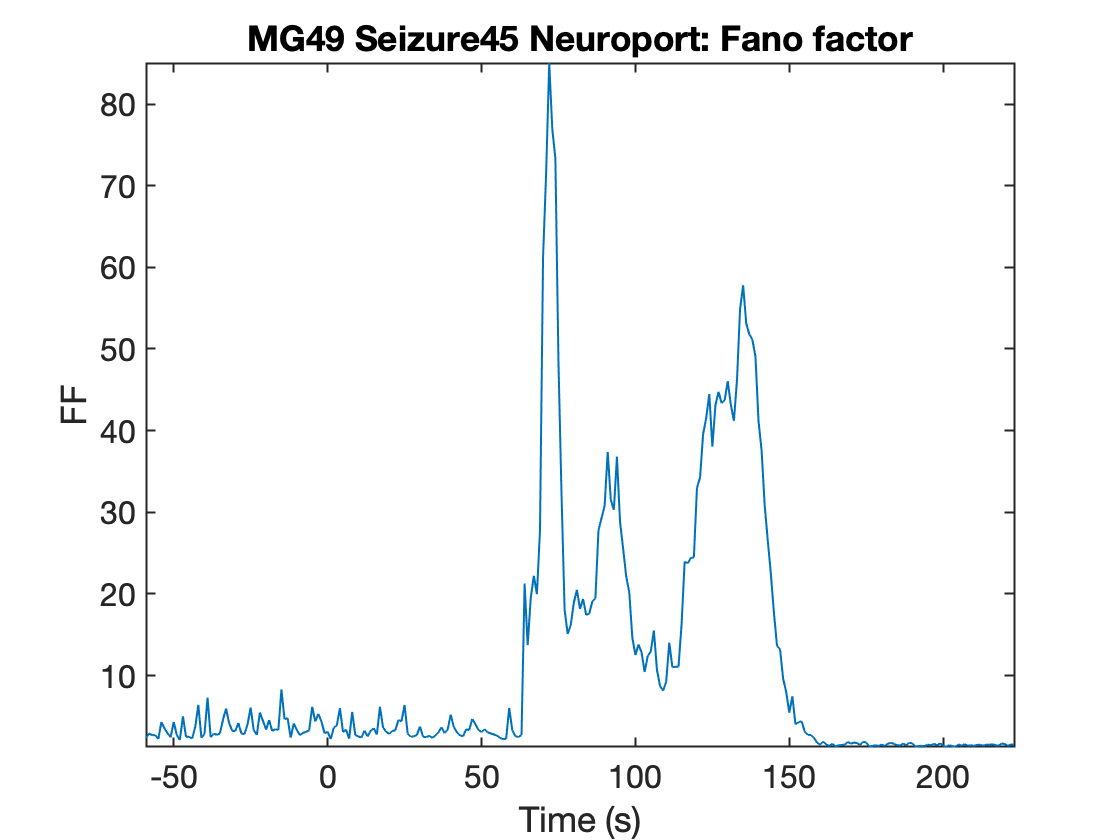


disp('Computing Fano factor')

if ~isfield(mea, 'ff')
	mea = mua_fano_factor(mea);
end

## Compute wave velocity at discharges

disp('Performing spatial linear regression')

Performing spatial linear regression


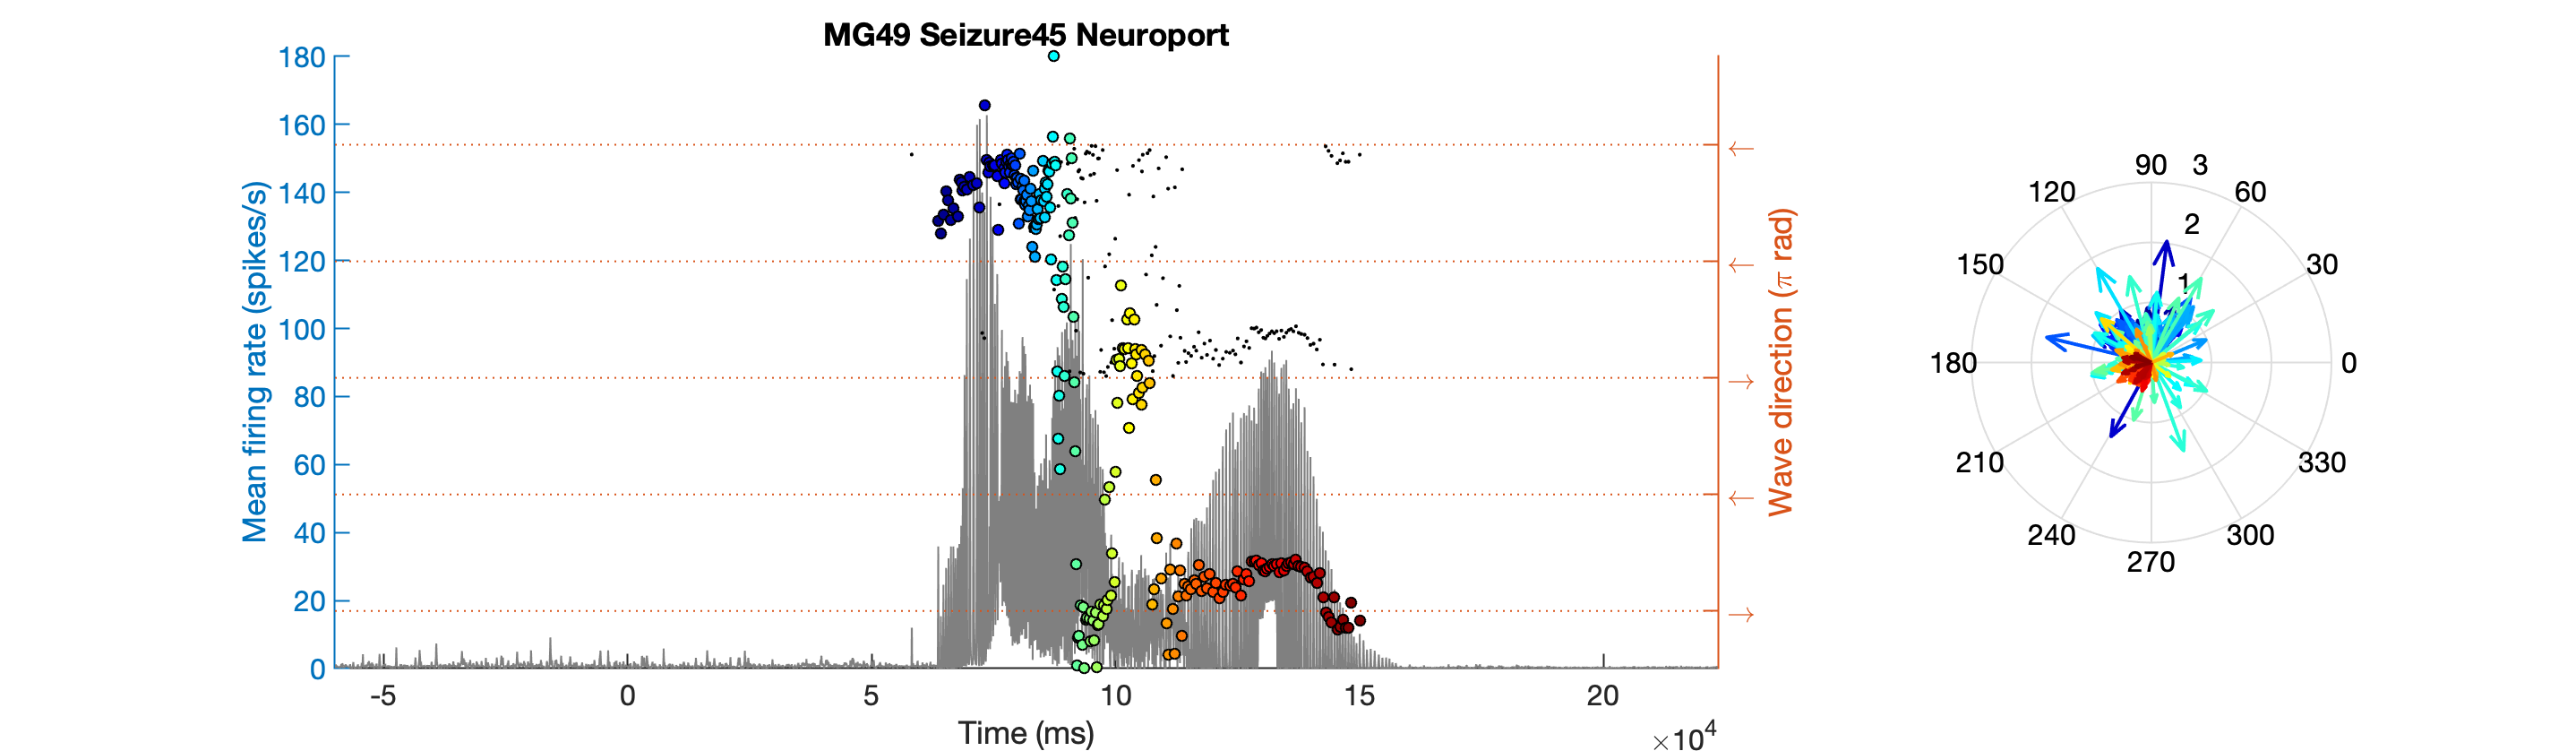


mea = wave_prop(mea);

## Save results

disp('Saving')

Saving



nn = strrep(Name, 'Seizure', '');

print(2, nn, '-dpng')

print(3, [nn '_FF'], '-dpng')

print(4, [nn, '_coh'], '-dpng')


save(Name, 'Date', 'ecog', 'mea', 'MatFile', 'Name', ...
    'Patient', '-v7.3')

## Define epochs and IDIs

The ictal wavefront epoch was defined as the time of the first channel?s mean minus its s.d. until the last channel?s mean plus its s.d. (Smith et al., 2016). [I think it should read "max" so I used max instead of mean]

% disp('Defining epochs')
% firingRateSm = smoothdata(mea.firingRate, 'gaussian', 100);
% peakRate = zeros(size(mea.firingRate, 2), 1);
% frT = mea.Time;
% inds = logical((frT >= 0) .* (frT <= 20));  % Look in the first 20 seconds of the seizure
% frT = frT(inds);
% mea.epochs = zeros(3, 1);
% 
% for i = 1:numel(peakRate)
% 	[~, ind] = max((firingRateSm(inds, i)));
% 	peakRate(i) = frT(ind);
% end
% 
% peakRate([68 72]) = [];  % These two electrodes look very different... one is definitely some kind of inhibitory cell
% [firstT, firstCh] = min(peakRate);
% [lastT, lastCh] = max(peakRate);
% 
% firstT = firstT - std(peakRate);
% lastT = lastT + std(peakRate);
% 
% mea.epochs(1) = firstT;  % Recruitment start time
% mea.epochs(2) = lastT;  % Post recruitment start time
% 
% % Discharge times: find peaks in firing rate
% hga = (mean(mea.hga, 2) - mean(mean(mea.hga(mea.Time < 0, :), 2))) / ...
% 	std(mean(mea.hga(mea.Time < 0, :), 2));
% hga = hga(ts(temp));  % high-gamma at discharge times
% mea.dischargeInds = ts(temp(hga > 2));
% mea.dischargeTimes = mea.Time(mea.dischargeInds);  % peaks with high-gamma at least one sd above the mean
% 
% mea.dischargeTimes(mea.dischargeTimes < mea.epochs(2)) = [];  % exclude recruitment discharges
% mea.dischargeTimes(mea.dischargeTimes > (mea.Time(end) - mea.Padding(2))) = [];  % exclude post termination discharges
% 
% mea.IDIs = diff(mea.waveTimes);
% mea.cov = zeros(floor((numel(mea.IDIs) - 10) / 3), 1);
% for i = 1:numel(mea.cov)
% 	ii = 3*(i-1);
% 	interval = min(30, numel(mea.IDIs) - ii);
% 	temp = mea.IDIs(ii+1:ii+interval);
% 	mea.cov(i) = std(temp) / mean(temp);
% end
% 
% [~, mea.epochs(3)] = max(diff(mea.cov));
% mea.epochs(3) = mea.dischargeTimes(3 * (mea.epochs(3) - 1) + 1);
% mea.dischargeTimes = mea.Time(mea.dischargeInds);
